# Autonomous Vehicle Models

## 1- Perception Block

For the realization of perception functionalities, the simulation of real physical measurements will 

be realized by an ideal radar sensor in MOBATSim.

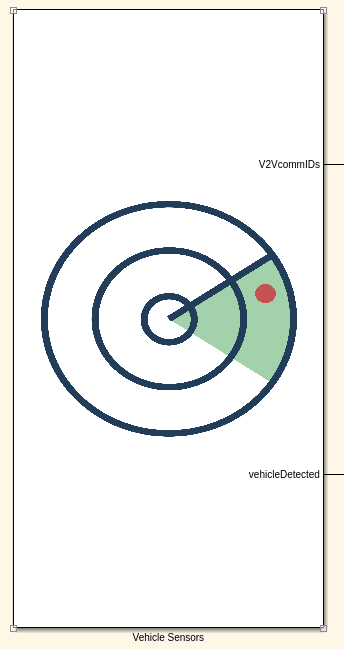

The tunable properties are of the `Vehicle_id`, `Tsample`, `OffsetTime`.

    properties
        Vehicle_id
        Tsample
        OffsetTime
    end
    
    % Pre-computed constants
    properties(Access = private)
        vehicle  %Ego Vehicle
        Vehicles= evalin('base','Vehicles');    %Other Vehicles (Used to generate the distance value)
    end

These properties will be used as parametrization of each sensor of an vehicle. Every vehicle got his own sensor `VehicleSensors`.

The user of the perception block is to locate vehicles in front of itself. So there can be two cases: Another vehicle is in front of the vehicle or no other vehicle ist detected by the radar sensor. The detection will be made in each simulation step.

        function [V2VcommIDs, vehicleDetected] = stepImpl(obj)

To realize the functionallity of the detection other vehicles, there will be used some helper functions.

            function [leadingVehicleID, distanceToLeading, rearVehicleID, distanceToRear] = detectVehicles(obj ,car, Vehicles)

The function `detectVehicles()` will detect other vehicles.

                function [frontDetection, rearDetection] = findVehiclesOnTheSameRoute(~,car,Vehicles)

The function `findVehiclesOnTheSameRoute()` will locate the other vehicle on the same route, if its driving in this segment of the map.

                    function frontDetection = findVehiclesOnTheNextRoute(~,car,Vehicles)

The function `findVehiclesOnTheNextRoute() `will locate the other vehicle on the next route, if its driving in next segment of the map.

                        function rearDetection = findVehiclesOnThePreviousRoutes(~,car,Vehicles)

The `findVehiclesOnThePreviousRoutes()` will locate the other vehicle on the previous route, if its driving in the previous segment of the map.

In the following diagram is the using of the functions showed.

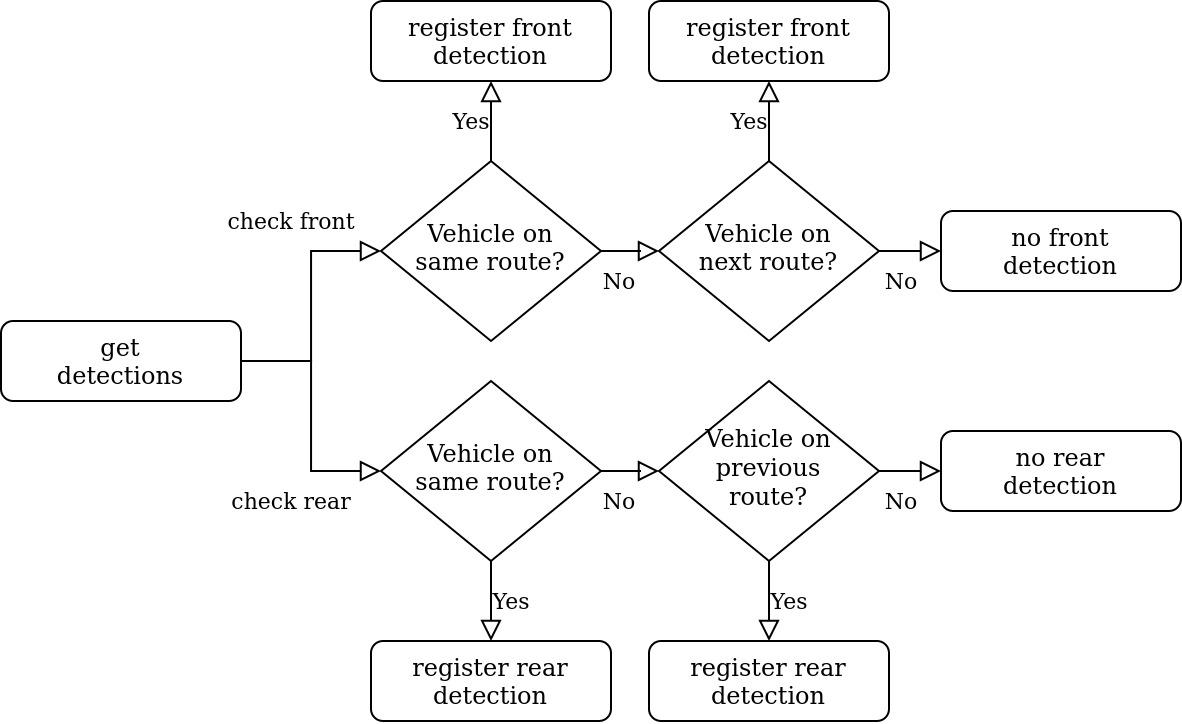

## 2-Vehicle Path Planner

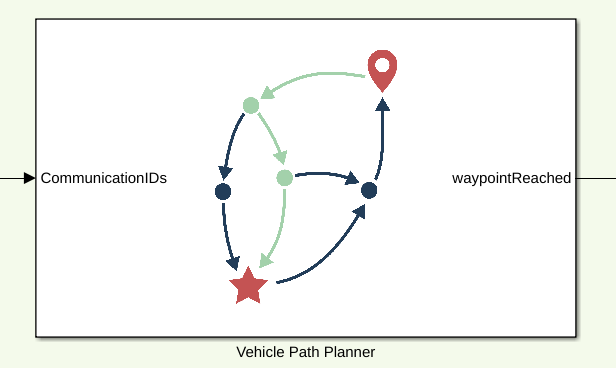

## 3-Vehicle V2I Output

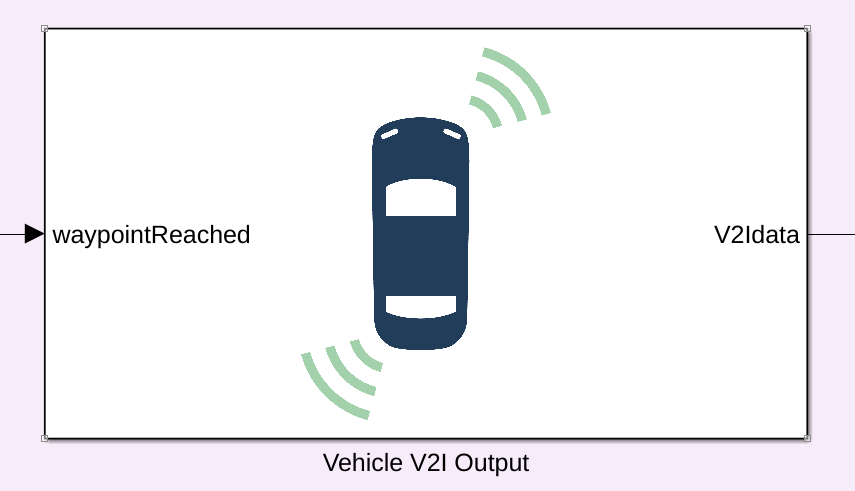

## 4-Vehicle Behavioural Planner

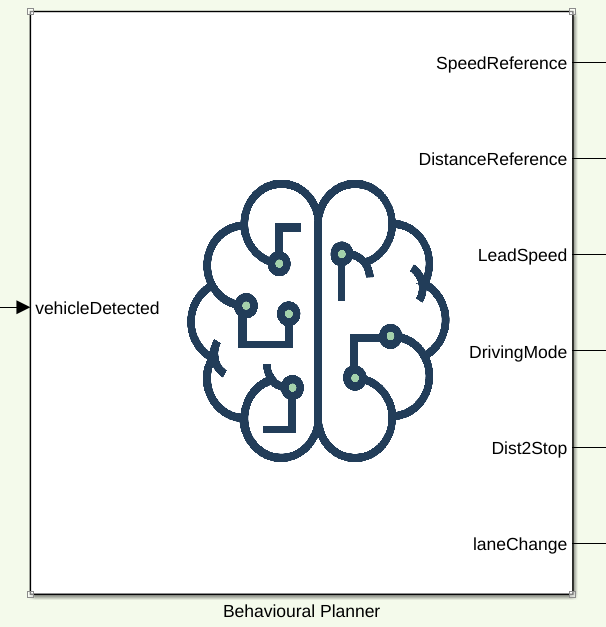

## 5-Vehicle Safety Filter

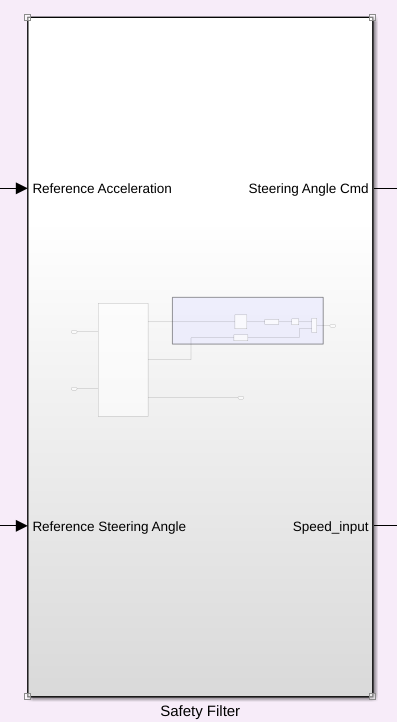

## 6-Vehicle Local Trajectory Planner 

## 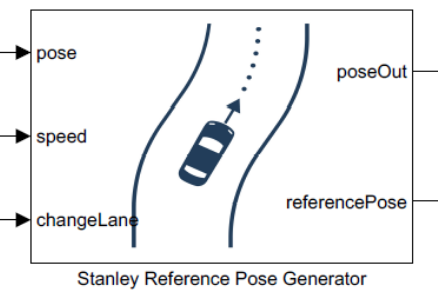

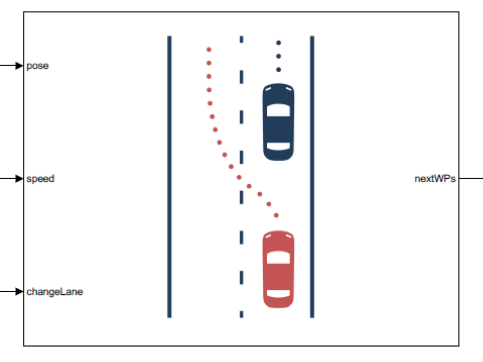

## 7-Kinematic Vehicle Model